Code for backward projection.

clear
colormap gray
mex -v GCC='/usr/bin/g++-6' -R2018a forward_projection.cpp

Verbose mode is on.
... Looking for compiler 'g++' ...
... Executing command 'which g++' ...Yes ('/usr/bin/g++').
... Executing command 'g++ -print-file-name=libstdc++.so' ...Yes ('/usr/lib/gcc/x86_64-linux-gnu/7/libstdc++.so').
... Executing command 'g++ -dumpversion' ...Yes ('7').
... Executing command 'which g++' ...Yes ('/usr/bin/g++').
... Looking for folder '/usr' ...Yes.
... Executing command 'g++ -dumpmachine' ...Yes ('x86_64-linux-gnu').
Found installed compiler 'g++'.
Set INCLUDE = /usr/lib/gcc/x86_64-linux-gnu/7/include;/usr/include/c++/7;/usr/include/c++/7/x86_64-linux-gnu;/usr/include/c++/7/backward;/usr/lib/gcc/x86_64-linux-gnu/7/include;/usr/include/c++/7;/usr/include/c++/7/x86_64-linux-gnu;/usr/include/c++/7/backward;
Options file details
-------------------------------------------------------------------
	Compiler location: /usr/bin/g++-6
	Options file: /home/veritas/.matlab/R2019b/mex_C++_glnxa64.xml
	CMDLINE2 : /usr/bin/g++-6 -pthread -Wl,--no-undefined  -shared -O -

/usr/bin/g++-6 -c -DMX_COMPAT_64  -DMATLAB_MEXCMD_RELEASE=R2018a  -DUSE_MEX_CMD   -D_GNU_SOURCE -DMATLAB_MEX_FILE  -I"/usr/local/MATLAB/R2019b/extern/include" -I"/usr/local/MATLAB/R2019b/simulink/include" -fexceptions -fPIC -fno-omit-frame-pointer -pthread -std=c++11 -O2 -fwrapv -DNDEBUG "/home/veritas/CLionProjects/CT1/forward_projection.cpp" -o /tmp/mex_126044468571188_20097/forward_projection.o
/usr/bin/g++-6 -c -DMX_COMPAT_64  -DMATLAB_MEXCMD_RELEASE=R2018a  -DUSE_MEX_CMD   -D_GNU_SOURCE -DMATLAB_MEX_FILE  -I"/usr/local/MATLAB/R2019b/extern/include" -I"/usr/local/MATLAB/R2019b/simulink/include" -fexceptions -fPIC -fno-omit-frame-pointer -pthread -std=c++11 -O2 -fwrapv -DNDEBUG "/usr/local/MATLAB/R2019b/extern/version/cpp_mexapi_version.cpp" -o /tmp/mex_126044468571188_20097/cpp_mexapi_version.o
/usr/bin/g++-6 -pthread -Wl,--no-undefined  -shared -O -Wl,--version-script,"/usr/local/MATLAB/R2019b/extern/lib/glnxa64/c_exportsmexfileversion.map" /tmp/mex_126044468571188_20097/forward_p

mex -v GCC='/usr/bin/g++-6' -R2018a backward_projection.cpp

Verbose mode is on.
... Looking for compiler 'g++' ...
... Executing command 'which g++' ...Yes ('/usr/bin/g++').
... Executing command 'g++ -print-file-name=libstdc++.so' ...Yes ('/usr/lib/gcc/x86_64-linux-gnu/7/libstdc++.so').
... Executing command 'g++ -dumpversion' ...Yes ('7').
... Executing command 'which g++' ...Yes ('/usr/bin/g++').
... Looking for folder '/usr' ...Yes.
... Executing command 'g++ -dumpmachine' ...Yes ('x86_64-linux-gnu').
Found installed compiler 'g++'.
Set INCLUDE = /usr/lib/gcc/x86_64-linux-gnu/7/include;/usr/include/c++/7;/usr/include/c++/7/x86_64-linux-gnu;/usr/include/c++/7/backward;/usr/lib/gcc/x86_64-linux-gnu/7/include;/usr/include/c++/7;/usr/include/c++/7/x86_64-linux-gnu;/usr/include/c++/7/backward;
Options file details
-------------------------------------------------------------------
	Compiler location: /usr/bin/g++-6
	Options file: /home/veritas/.matlab/R2019b/mex_C++_glnxa64.xml
	CMDLINE2 : /usr/bin/g++-6 -pthread -Wl,--no-undefined  -shared -O -

/usr/bin/g++-6 -c -DMX_COMPAT_64  -DMATLAB_MEXCMD_RELEASE=R2018a  -DUSE_MEX_CMD   -D_GNU_SOURCE -DMATLAB_MEX_FILE  -I"/usr/local/MATLAB/R2019b/extern/include" -I"/usr/local/MATLAB/R2019b/simulink/include" -fexceptions -fPIC -fno-omit-frame-pointer -pthread -std=c++11 -O2 -fwrapv -DNDEBUG "/home/veritas/CLionProjects/CT1/backward_projection.cpp" -o /tmp/mex_126045945119794_20097/backward_projection.o
/usr/bin/g++-6 -c -DMX_COMPAT_64  -DMATLAB_MEXCMD_RELEASE=R2018a  -DUSE_MEX_CMD   -D_GNU_SOURCE -DMATLAB_MEX_FILE  -I"/usr/local/MATLAB/R2019b/extern/include" -I"/usr/local/MATLAB/R2019b/simulink/include" -fexceptions -fPIC -fno-omit-frame-pointer -pthread -std=c++11 -O2 -fwrapv -DNDEBUG "/usr/local/MATLAB/R2019b/extern/version/cpp_mexapi_version.cpp" -o /tmp/mex_126045945119794_20097/cpp_mexapi_version.o
/usr/bin/g++-6 -pthread -Wl,--no-undefined  -shared -O -Wl,--version-script,"/usr/local/MATLAB/R2019b/extern/lib/glnxa64/c_exportsmexfileversion.map" /tmp/mex_126045945119794_20097/backwar

Input variables

img_size = 256;
input_array = single(phantom(img_size));

num_det_pix=368;
det_pix_len=1;  % In mm

img_pix_len_x=1;  % In mm
img_pix_len_y=1;  % In mm

sampling_interval=1;  % In mm
num_views=180;
projection_range=180;  % In degrees

fftw('planner', 'estimate');

my_sinogram = forward_projection(input_array, num_det_pix, det_pix_len,...
    img_pix_len_x, img_pix_len_y, sampling_interval, num_views,...
    projection_range);

thetas = (0:(num_views-1)) * (projection_range/num_views);
sinogram = radon(input_array, thetas);

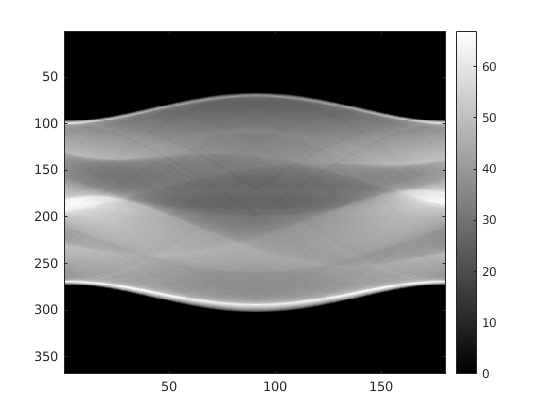

imagesc(my_sinogram)
colorbar()

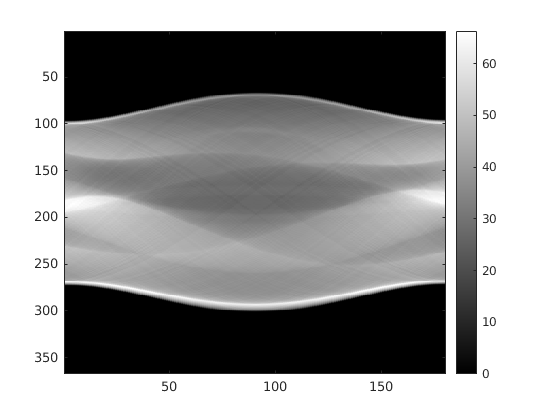


imagesc(sinogram)
colorbar()

my_recon = filtered_backprojection_matlab(my_sinogram,...
    img_size, img_size, img_pix_len_x, img_pix_len_y,...
    det_pix_len, projection_range);

my_mex_recon = filtered_backprojection_partial_mex( ...
    my_sinogram,img_size, img_size, img_pix_len_x, ...
    img_pix_len_y, det_pix_len, projection_range);

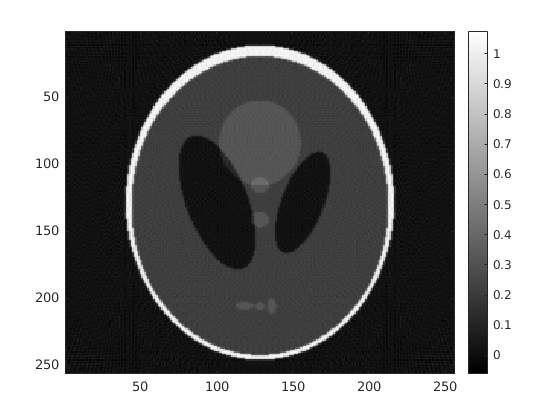

imagesc(my_recon)
colorbar()

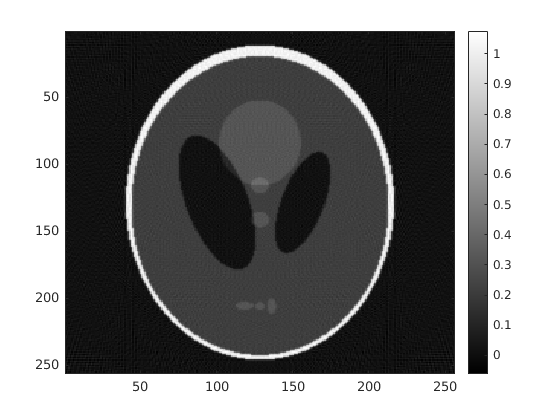

imagesc(my_mex_recon)
colorbar()

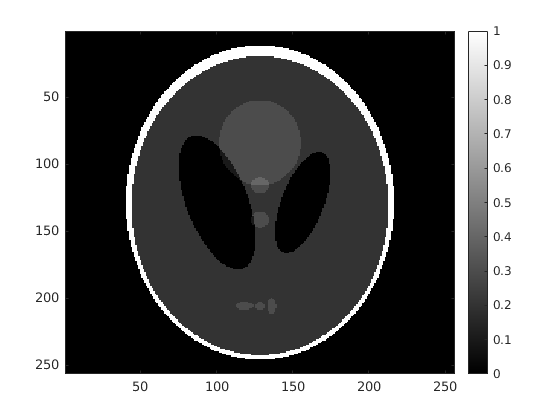

imagesc(input_array)
colorbar()

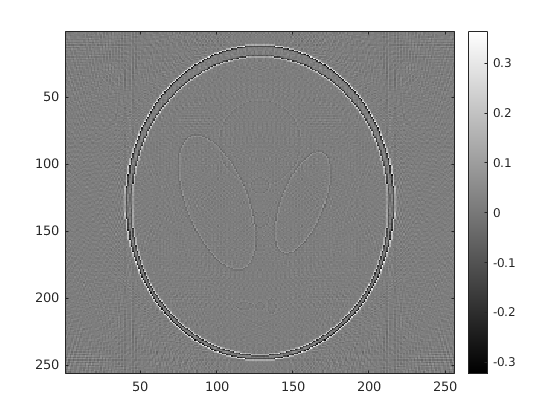

imagesc(my_recon - input_array)
colorbar()

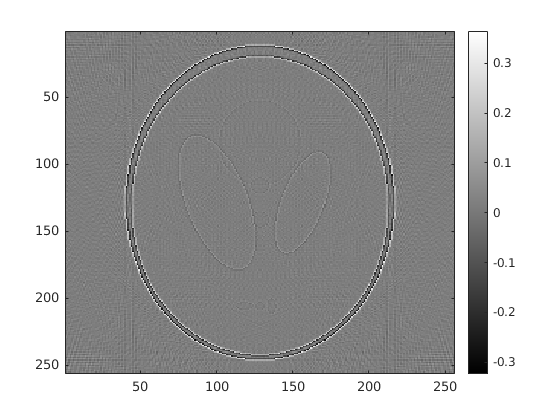

imagesc(my_mex_recon - input_array)
colorbar()

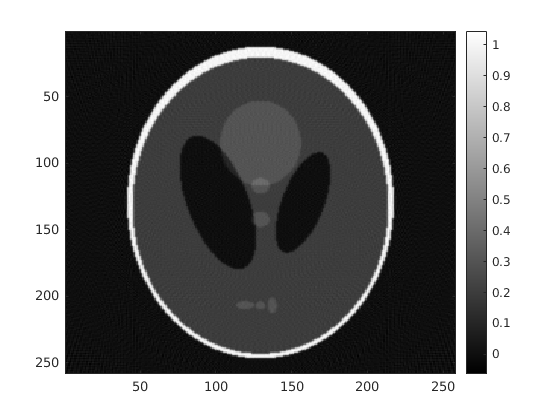

recon = iradon(sinogram, thetas);
imagesc(recon)
colorbar()

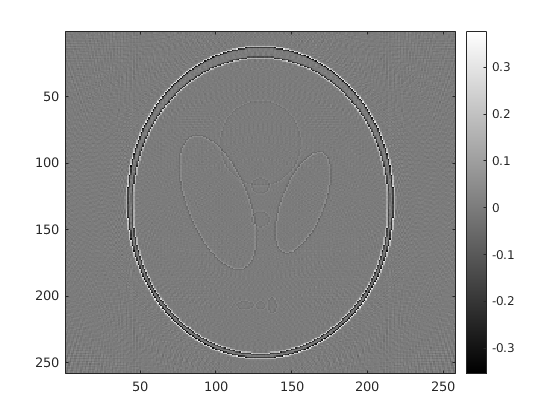

imagesc(recon - padarray(input_array, [1, 1], 0, 'both'))
colorbar()

orig = @() iradon(sinogram, thetas);
my_matlab = @() filtered_backprojection_matlab(my_sinogram,...
    img_size, img_size, img_pix_len_x, img_pix_len_y,...
    det_pix_len, projection_range);
my_partial_mex = @() filtered_backprojection_partial_mex( ...
    my_sinogram,img_size, img_size, img_pix_len_x, ...
    img_pix_len_y, det_pix_len, projection_range);

orig_time = timeit(orig);
mat_time = timeit(my_matlab);
partial_mex_time = timeit(my_partial_mex);
disp(orig_time)

    0.0096



disp(mat_time)

    0.1481



disp(partial_mex_time)

    0.1124

